%CW2
%Variables
clear; clc; close all;
format shortEng
syms R L C i(t) t u0 uc(t)
duc = diff(uc,t);
duc_second = diff(uc,t, 2);
equation = (u0 == uc + R * C * duc + L * C * duc_second);
current_equation = (i == C*duc);

%Case 1
% u0_values = 0; %u zasilania
% uc0_values = [1,3,5]; %spadek na pojemnosci
% duc0_value = 0; %pochodna
% R_value = 1; 
% L_value = 10e-3;
% C_values = 1e-3; % Brakujaca wartosc C

%Case 2
% u0_values = [1,3,5];
% uc0_values = 0;
% duc0_value = 0;
% 
% R_value = 1; 
% L_value = 10e-3;
% C_values = 1e-3;


%Case 3
u0_values = 5;
uc0_values = 0;
duc0_value = 0;

R_value = 1; 
L_value = 10e-3;
C_values = [0.1e-3,1e-3,40e-3];

Rozwiązanie analityczne uc(t) oraz i(t)
 dla uc(0) = 0 V, u0 = 5 V,
 R = 1, L = 1.000000e-02, C = 1.000000e-04:


uc(t) =


$$5-\frac{5\,\sqrt{399}\,{\mathrm{e}}^{-50\,t}\,\sin\left(50\,\sqrt{399}\,t\right)}{399}-5\,{\mathrm{e}}^{-50\,t}\,\cos\left(50\,\sqrt{399}\,t\right)$$

i(t) =


$$\frac{10\,\sqrt{399}\,{\mathrm{e}}^{-50\,t}\,\sin\left(50\,\sqrt{399}\,t\right)}{399}$$

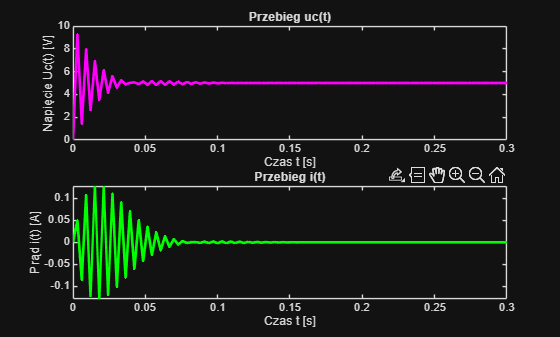

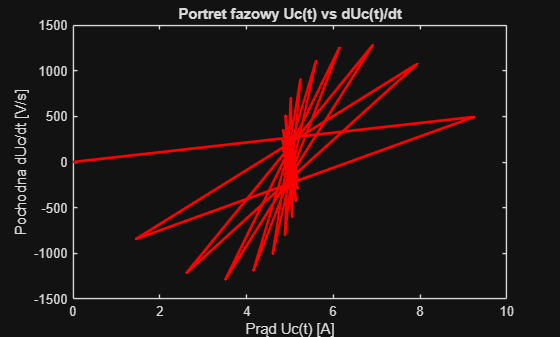

Rozwiązanie analityczne uc(t) oraz i(t)
 dla uc(0) = 0 V, u0 = 5 V,
 R = 1, L = 1.000000e-02, C = 1.000000e-03:


uc(t) =


$$5-\frac{5\,\sqrt{39}\,{\mathrm{e}}^{-50\,t}\,\sin\left(50\,\sqrt{39}\,t\right)}{39}-5\,{\mathrm{e}}^{-50\,t}\,\cos\left(50\,\sqrt{39}\,t\right)$$

i(t) =


$$\frac{10\,\sqrt{39}\,{\mathrm{e}}^{-50\,t}\,\sin\left(50\,\sqrt{39}\,t\right)}{39}$$

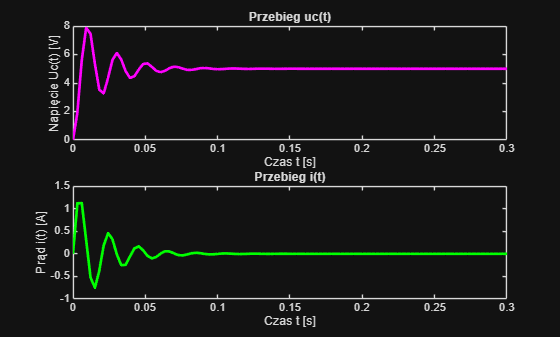

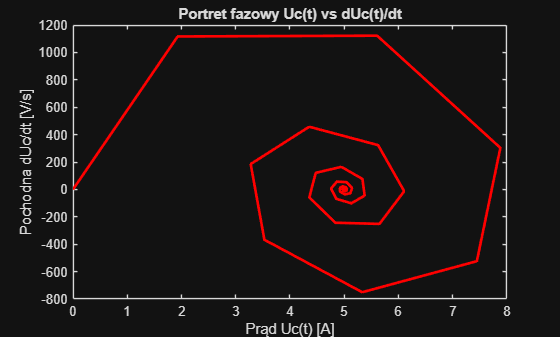

Rozwiązanie analityczne uc(t) oraz i(t)
 dla uc(0) = 0 V, u0 = 5 V,
 R = 1, L = 1.000000e-02, C = 4.000000e-02:


uc(t) =


$$5-250\,t\,{\mathrm{e}}^{-50\,t}-5\,{\mathrm{e}}^{-50\,t}$$

i(t) =


$$500\,t\,{\mathrm{e}}^{-50\,t}$$

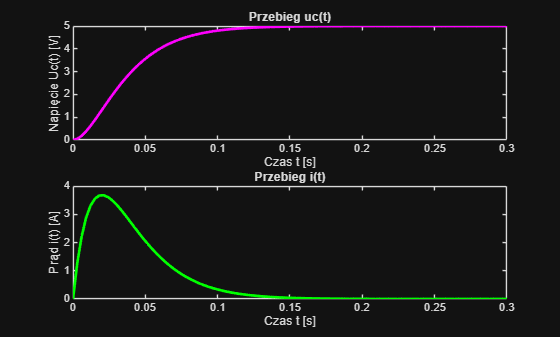

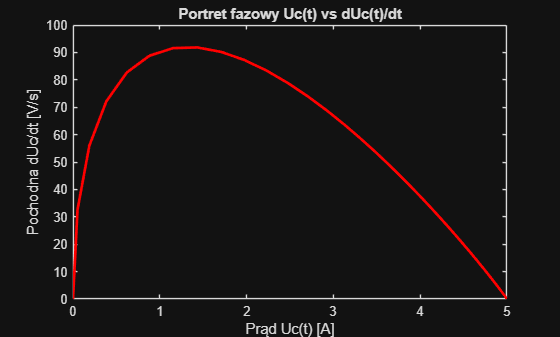

for C_value = C_values
    for u0_value = u0_values
        for uc0_value = uc0_values
        
            conds = [uc(0) == uc0_value, duc(0)==duc0_value] ; %war poczatkowy
            % Rozwiązanie analityczne
            uc_sol(t) = dsolve(subs(equation, [u0, R, L, C], [u0_value, R_value, L_value, C_value]), conds);
        
            % i(t) = C * duc/dt
            duc_sol(t) = diff(uc_sol(t), t);
            i_sol(t) = C_value * duc_sol(t);
                    
            fprintf(['Rozwiązanie analityczne uc(t) oraz i(t)\n dla uc(0) = %d V, u0 = %d V,' ...
                '\n R = %d, L = %d, C = %d:\n'], uc0_value, u0_value, R_value, L_value, C_value);
            disp('uc(t) =');
            disp(uc_sol(t));
        
            disp('i(t) =');
            disp(i_sol(t));
        
            t_plot_vec = linspace(0, 0.3, 100);
            uc_plot_vals = subs(uc_sol(t), t, t_plot_vec);
            i_plot_vals = subs(i_sol(t), t, t_plot_vec);
            duc_plot_vals = subs(duc_sol(t), t, t_plot_vec);
        
            figure
            grid on;
            subplot(2, 1, 1);
            plot(t_plot_vec, uc_plot_vals, LineWidth = 2, Color = "magenta");
            title(sprintf('Przebieg uc(t)'));
            xlabel('Czas t [s]'); ylabel('Napięcie Uc(t) [V]');
        
        
            subplot(2, 1, 2);
            plot(t_plot_vec, i_plot_vals, LineWidth = 2, Color = "green");
            title(sprintf('Przebieg i(t)'));
            xlabel('Czas t [s]'); ylabel('Prąd i(t) [A]');

            figure
            grid on;
            plot(uc_plot_vals, duc_plot_vals, LineWidth = 2, Color = "red");
            title(sprintf('Portret fazowy Uc(t) vs dUc(t)/dt'))
            xlabel('Prąd Uc(t) [A]'); ylabel('Pochodna dUc/dt [V/s]');
        end
    end
end